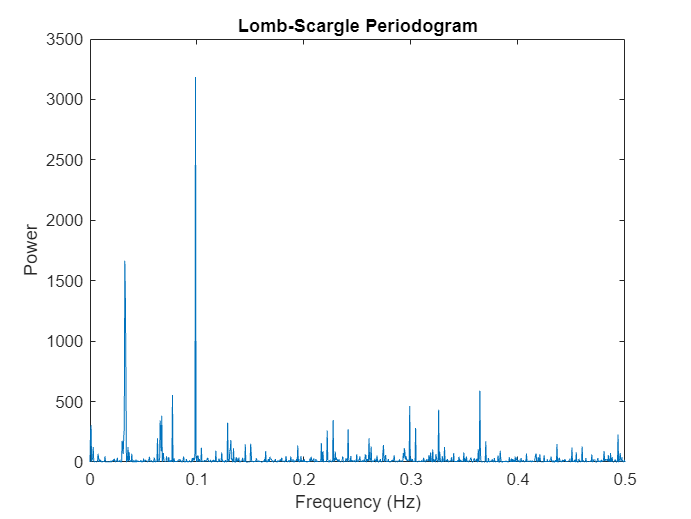

% Load and preprocess data
data =TeslaStockPrice; 
dates = datenum(data.Date);
closing_prices = data.Close;

% Lomb-Scargle Periodogram parameters
Fs = 1; % Sampling frequency
N = numel(dates); % Number of observations
freq_range = linspace(0, Fs/2, 1000); % Frequency range

% Split data into training and testing sets
train_ratio = 0.85; % 85% training data, 15% testing data
train_end = round(train_ratio * N);
train_dates = dates(1:train_end);
train_prices = closing_prices(1:train_end);
test_dates = dates(train_end+1:end);
test_prices = closing_prices(train_end+1:end);

% Parameters for gradient descent
max_iter = 1000;
learning_rate = 0.01;
lambda = .8; %L2 Regularization

% Lomb-Scargle Periodogram modeling
[frequencies, power, coefficient] = lomb_scale_periodogram(train_dates, train_prices, freq_range,  max_iter, learning_rate, lambda);

% Plot Lomb-Scargle Periodogram
figure;
plot(frequencies, power);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Lomb-Scargle Periodogram');


[M,i] = max(power);
max_f = frequencies(i);
a = coefficient(i,1);
b = coefficient(i,2);
signal = a* sin(2 * pi * max_f * test_dates) + b*sin(2 * pi * max_f * test_dates);

ls_mse = mean((signal - test_prices).^2);
ls_mape = mean(abs((signal - test_prices) ./ test_prices)) * 100;

fprintf('LOMB SCALE Model: MSE = %f, MAPE = %f%%\n', ls_mse, ls_mape);

LOMB SCALE Model: MSE = 76300.859798, MAPE = 86.899799%



% ARIMA modeling
[arima_forecast, arima_mse, arima_mape] = arima_model(train_prices, test_prices);

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue 
                _________    _____________    __________    ________

    Constant    0.0076067      0.0056784        1.3396       0.18038
    AR{1}         0.52135        0.28856        1.8067      0.070806
    AR{2}         0.42925        0.27793        1.5445       0.12248
    MA{1}        -0.50037        0.28259       -1.7706      0.076622
    MA{2}        -0.46705        0.27569       -1.6941      0.090247
    Variance       29.759        0.41915        70.998             0



fprintf('ARIMA Model: MSE = %f, MAPE = %f%%\n', arima_mse, arima_mape);

ARIMA Model: MSE = 8884.737744, MAPE = 28.778452%



% Lomb-Scargle Periodogram function

function [freq, power,coefficient] = lomb_scale_periodogram(t, y, frequencies, max_iter, learning_rate, lambda)
    % Mean-centering the signal
    y_mean = mean(y);
    y_centered = y - y_mean;
    
    % Number of observations
    N = length(t);
    
    % Initialize power array
    power = zeros(size(frequencies));
    
    % Loop through each frequency
    for i = 1:length(frequencies)
        omega = 2 * pi * frequencies(i);
        
        % Initialize parameters
        a = 1;
        b = 1;
        
        % Gradient descent
        for iter = 1:max_iter
            % Compute residuals
            residuals = y_centered - a * cos(omega * t) + b * sin(omega * t);
            
            % Compute gradients
            grad_a = -2 * sum(residuals .* cos(omega * t)) / N + 2 * lambda * a;
            grad_b = -2 * sum(residuals .* sin(omega * t)) / N + 2 * lambda * b;
            
            % Update parameters with L2 regularization
            a = a - learning_rate * grad_a;
            b = b - learning_rate * grad_b;
        end
        
        % Compute power at this frequency
        power(i) = (a^2 + b^2) ; %power for a signal with addition of two sine waves of frequencies a and b
        coefficient(i,1)  = a;
        coefficient(i,2) = b;
    end
    
    % Return frequencies and corresponding power
    freq = frequencies;
end

% ARIMA model function
function [forecast1, mse, mape] = arima_model(training_data, testing_data)
    model = arima(2, 1, 2); % Example ARIMA(p, d, q) parameters
    model = estimate(model, training_data);
    [forecast1, ~] = forecast(model, numel(testing_data), 'Y0', training_data);
    
    mse = mean((forecast1 - testing_data).^2);
    mape = mean(abs((forecast1 - testing_data) ./ testing_data)) * 100;
end

